M = csvread(accMe)

M =             0            0
          0.2    0.0042303
          0.4            0
          0.6            0
          0.8            0
            1            0
          1.2            0
          1.4            0
          1.6            0
          1.8            0


x = M(:,1)

x =             0
          0.2
          0.4
          0.6
          0.8
            1
          1.2
          1.4
          1.6
          1.8


y = M(:,2)

y =             0
    0.0042303
            0
            0
            0
            0
            0
            0
            0
            0



plot(x,y)
[pk,lc] = findpeaks(y,x);
hold on
plot(lc,pk,'x')
[pkt,lct] = findpeaks(y,x,'Threshold',6e-2);
plot(lct,pkt,'o','MarkerSize',12)
speed = string(round(rms(pkt),3, 'significant'))

speed = "2.33"

speed = 'Mean '  + speed

speed = "Mean 2.33"

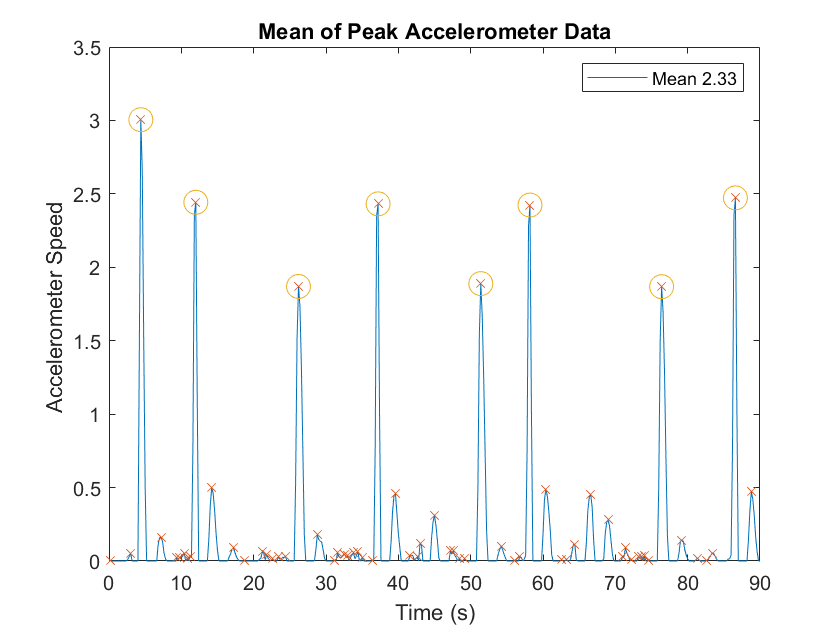


xlabel('Time (s)');
ylabel('Accelerometer Speed ');
title('Mean of Peak Accelerometer Data')
legend({speed},'Location','northeast')